clear;close;clc;
% Same algorithm as boot.xlm, 
% but starts a script based system instead of Simulink Simulation

% Working directory
currentFolder="C:\Users\Administrator\Documents\RNNMPC";
cd(currentFolder)

% Determine where your m-file's folder is.s
currentFolder = pwd;

% Add that folder plus all subfolders to the path.
addpath(genpath(currentFolder));

%Scenario parameters
% Scenario=currentFolder+"/Scenarios/"+"NCCAR.m";
[allData, scenario, sensors] = NCCAR();

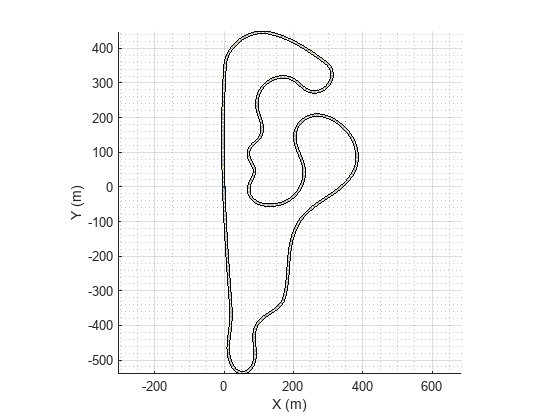


% Visualize Scenario
plot(scenario);


% % Extract EgoCars from scenario
% egoCarID1=Scenario.data.EgoCarId(1);
% 
% % Simulation time Stamps
% Ts=0.1;
% Te=10;
% T0=0;
% 

% % Create objects with Ego Car params
% 
% % Defualt setting EgoCar
% EgoCar1_params = Vehicle_Params(egoCarID1); % With default dynamics
% 
% % Extract initial state from scenario
% EgoCar1_params = EgoCar1_params.Set_iniStateFromScenario(Scenario.data);
% 

% % % Target cruise speed m/s
% % targetSpeed=15;
% 
% waypoints=Scenario.data.ActorSpecifications(egoCarID1).Waypoints(:,1:2);
% 
% laneDetectRange=linspace(0,100,101);